# Taller 1

 Punto 1.1

Definimos y limpiamos la base de datos 

%PUNTO 1.1
clc; clear all;
ds2 = readtable("RATING.xlsx", "UseExcel", false);
ds=rmmissing(ds2)

ds = 3416×25 table
    imdb_score           color           num_critic_for_reviews    duration    director_facebook_likes    actor_3_facebook_likes    actor_1_facebook_likes      gross       num_voted_users    cast_total_facebook_likes    facenumber_in_poster    num_user_for_reviews       language           country        content_rating     budget     title_year    actor_2_facebook_likes    aspect_ratio    movie_facebook_likes         director_name               actor_1_name                actor_3_name             actor_2_name          genres    
    __________

%unimos las dos tablas
ds1 = readtable('RATING.xlsx','Sheet','USA GDP');

ds1.Properties.VariableNames{1} = 'year';
ds.Properties.VariableNames{17} = 'year';
T = join( ds , ds1);
%calculamos el gross como porcentaje del dgp 
p= (T.gross./T.GDPUS_USD_)*100;
%calculamos el  budget como porcentaje del dgp 
x=(T.budget./T.GDPUS_USD_)*100;
ds.gdp=(T.gross./T.GDPUS_USD_)*100;
%PUNTO 3
T.color = categorical(T.color);
T.language = categorical(T.language);
T.country = categorical(T.country);
T.language = categorical(T.language);
T.content_rating = categorical(T.content_rating);
T.director_name = categorical(T.director_name);
T.actor_1_name = categorical(T.actor_1_name);
T.actor_2_name = categorical(T.actor_2_name);
T.actor_3_name = categorical(T.actor_3_name);
ds.genres = categorical(ds.genres);
% le pedimos a matlab que nos haga la estadisticas descriptivas
format compact
summary (ds); 

Variables:
    imdb_score: 3416×1 double
        Values:
            Min         1.6   
            Median      6.6   
            Max         9.3   
    color: 3416×1 cell array of character vectors
    num_critic_for_reviews: 3416×1 double
        Values:
            Min           1   
            Median      138   
            Max         813   
    duration: 3416×1 double
        Values:
            Min          37   
            Median      106   
            Max         330   
    director_facebook_likes: 3416×1 double
        Values:
            Min            0  
            Median        62  
            Max        23000  
    actor_3_facebook_likes: 3416×1 double
        Values:
            Min            0  
            Median       440  
            Max        23000  
    actor_1_facebook_likes: 3416×1 double
        Values:
            Min             0 
 

%PUNTO 4 

Punto 1.2 

Estimar los errores normales

%% Simulaciones

%% Errores Normales

% definimos la semilla para que los numeros aleatorios se generen en un
% mismo rango aleatorio siempre (minimiza la posibilidad de que salgan cosas
% locas).
%% Ralizamos un modelo 
%Y: El rating imdb para cada película i 𝑥1: 
% x1 = num_critic_for_reviews
%𝑥2: duration
%�3: director_facebook_likes
%�4: num_voted_users
%𝑥5: num_user_for_reviews 
% 𝑥6: movie_facebook_likes
%�7: Ganancias como % del PIB
% 𝑔𝑖 :genres
% Generamos el modelo:
%

## Punto 1


% Realizamos la estimacion del modelo 

Modelo2=fitlm(ds,['imdb_score~num_critic_for_reviews' ...
    '+duration+director_facebook_likes+director_facebook_likes' ...
    '+num_voted_users+num_user_for_reviews +movie_facebook_likes+gdp+genres'])

Modelo2 = Linear regression model:
    imdb_score ~ 1 + num_critic_for_reviews + duration + director_facebook_likes + num_voted_users + num_user_for_reviews + movie_facebook_likes + genres + gdp

Estimated Coefficients:
                                Estimate          SE         tStat        pValue  
                               ___________    __________    ________    __________
    (Intercept)                      4.714      0.085532      55.114             0
    num_critic_for_reviews       0.0015499    0.00018869      8.2139    3.0109e-16
    duration                     0.0087439    0.00073192      11.947    2.9754e-32
    director_facebook_likes     1.6066e-06    4.9475e-06     0.32472       0.74541
    num_voted_users             3.4361e-06    1.8043e-07     

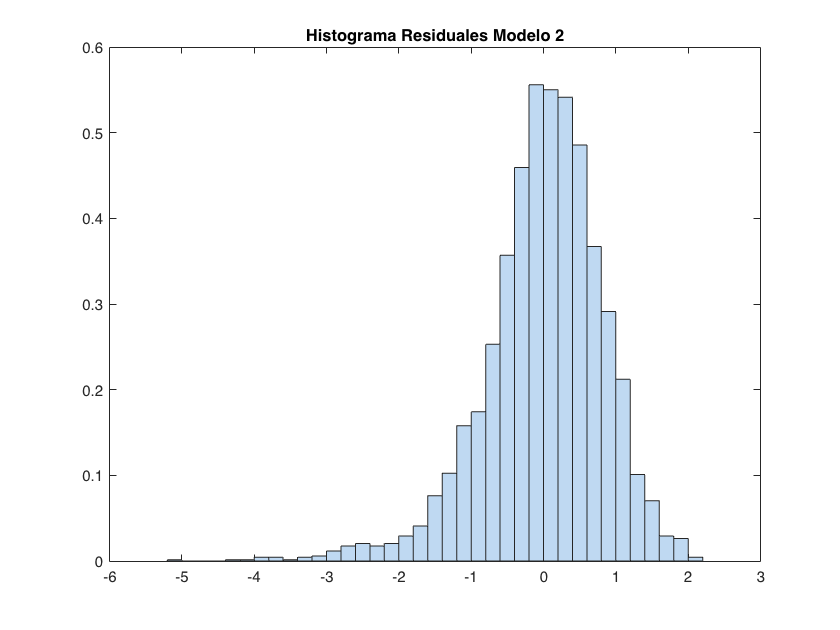

%% Observamos la distribucion del modelo 
figure
plotResiduals(Modelo2)
title('Histograma Residuales Modelo 2')

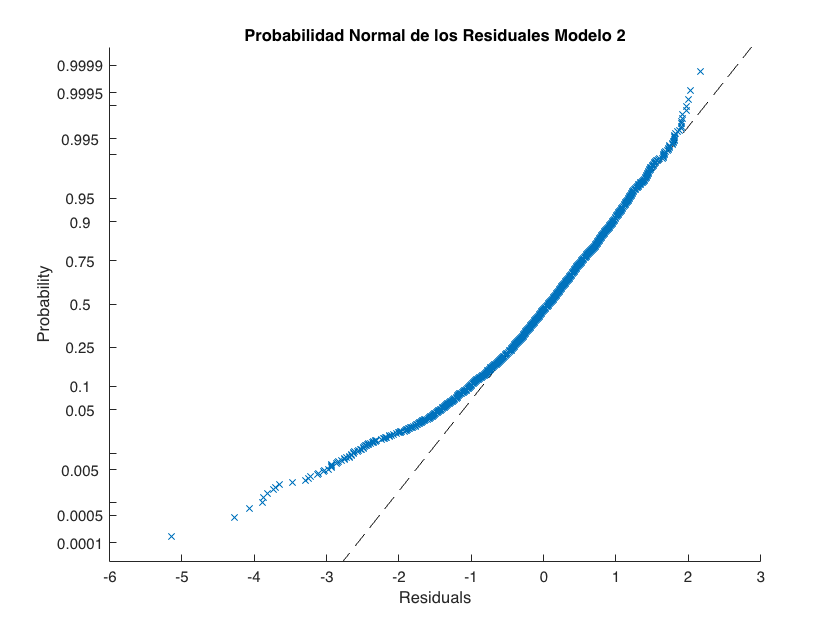

plotResiduals(Modelo2,'probability')
title('Probabilidad Normal de los Residuales Modelo 2')

% Creamos la tabla para la informacion 
%% el modelo poner los intervalos +1,96 y -1,96
%4.2. creando una tabla con los criterios de información obtenidos:

MODELOS = {'Modelo 2'};
MSE=[Modelo2.MSE]; 
%LogLikelihood=[Modelo1.LogLikelihood;Modelo2.LogLikelihood];
AIC=[Modelo2.ModelCriterion.AIC];
SIC=[Modelo2.ModelCriterion.BIC];
R2=[Modelo2.Rsquared.Ordinary];
R2_Ajustado=[Modelo2.Rsquared.Adjusted];

CRITERIO = table(R2,R2_Ajustado,MSE,AIC,SIC,'RowNames',MODELOS)

CRITERIO = 1×5 table
                  R2       R2_Ajustado      MSE       AIC       SIC  
                _______    ___________    _______    ______    ______
    Modelo 2    0.38506      0.38089      0.68469    8424.2    8571.4

## Punto 1

% Definamos las semilla 
rng(1234)

% a. Generamos 50 errores aletarios para el modelo
S=std(Modelo2.Residuals.Raw,'omitnan');
mu=mean(Modelo2.Residuals.Raw);
RNormal=normrnd(0,S,[1,1]);

% Intervalo de confianza del 95%
% Suponiendo un error con distribucion normal sin simulaciones 

betahat=Modelo2.Coefficients.Estimate;
LWh1_Normal=betahat(1,1)+betahat(2,1)+betahat(3,1)+betahat(4,1)+betahat(5,1)+betahat(6,1)+betahat(7,1)+betahat(8,1);


% Estimamos el exponencial del modelo2
% densidad y limites de prediccion:
Wage1_Normal=exp(RNormal'+LWh1_Normal)

Wage1_Normal = 71.8774

pwnormal=prctile(Wage1_Normal, [2.5 97.5])

pwnormal =    71.8774   71.8774


a=[1.96,-1.96]

a =     1.9600   -1.9600


pwnormal= pwnormal - a

pwnormal =    69.9174   73.8374


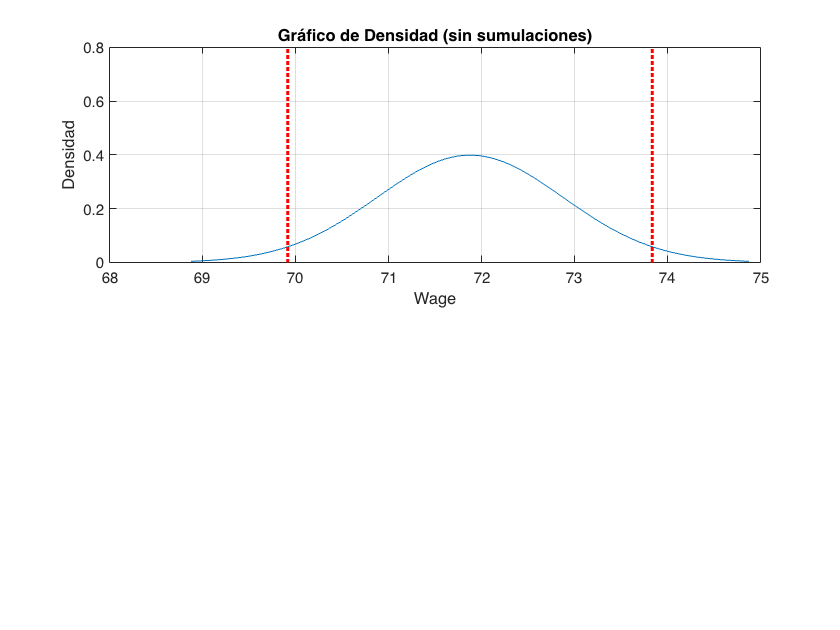

%% Realizamos las graficas  de densidad con el intervalo de confianza
subplot(2,1,1)
ksdensity(Wage1_Normal)
grid on
line([pwnormal(1,1) pwnormal(1,1)], ylim*2,'Color','r','LineStyle',':','LineWidth',2)
line([pwnormal(1,2) pwnormal(1,2)], ylim,'Color','r','LineStyle',':','LineWidth',2)
xlabel('Wage') 
ylabel('Densidad')
title('Gráfico de Densidad (sin sumulaciones)')

## Punto 2


% Definamos las semilla 
rng(1234)

% a. Generamos 50 errores aletarios para el modelo
S=std(Modelo2.Residuals.Raw,'omitnan');
mu=mean(Modelo2.Residuals.Raw);
RNormal=normrnd(0,S,[1,50]);

% Intervalo de confianza del 95%
% Suponiendo un error con distribucion normal sin simulaciones 

betahat=Modelo2.Coefficients.Estimate;
LWh1_Normal=betahat(1,1)+betahat(2,1)+betahat(3,1)+betahat(4,1)+betahat(5,1)+betahat(6,1)+betahat(7,1)+betahat(8,1);


% Estimamos el exponencial del modelo2
% densidad y limites de prediccion:
Wage1_Normal=exp(RNormal'+LWh1_Normal)

Wage1_Normal =    71.8774
  245.0772
  131.3023
  418.5045
  465.0798
  112.3498
  108.7690
  469.4720
  312.2301
  258.4228


pw1normal=prctile(Wage1_Normal, [2.5 97.5])

pw1normal =    14.2735  535.5021


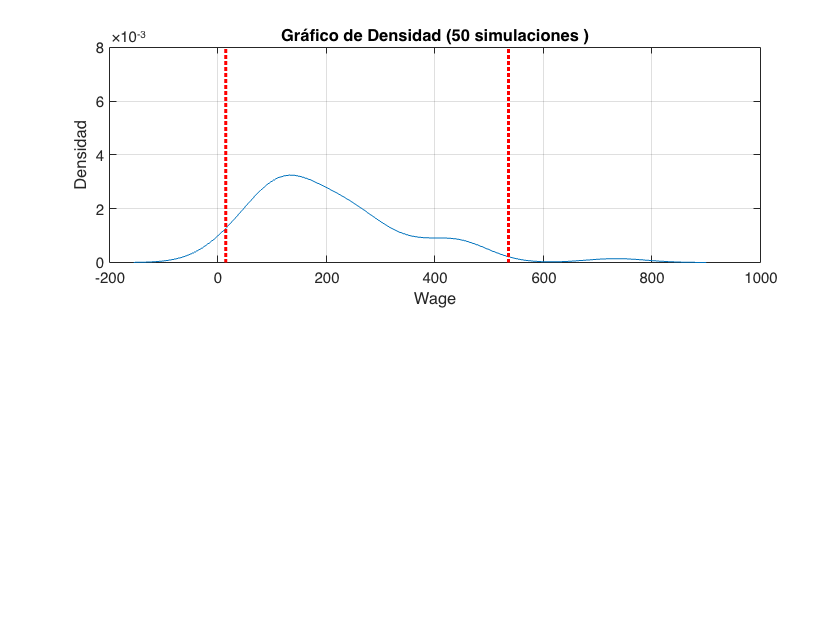




%% Punto 1.2.2

%% Realizamos las graficas  de densidad con el intervalo de confianza
subplot(2,1,1)
ksdensity(Wage1_Normal)
grid on
line([pw1normal(1,1) pw1normal(1,1)], ylim*2,'Color','r','LineStyle',':','LineWidth',2)
line([pw1normal(1,2) pw1normal(1,2)], ylim,'Color','r','LineStyle',':','LineWidth',2)
xlabel('Wage') 
ylabel('Densidad')
title('Gráfico de Densidad (50 simulaciones )')


% Definamos las semilla 
rng(1234)

% b. Generamos 50 errores aletarios para el modelo
S=std(Modelo2.Residuals.Raw,'omitnan');
mu=mean(Modelo2.Residuals.Raw);
RNormal=normrnd(0,S,[1,500]);

% Intervalo de confianza del 95%
% Suponiendo un error con distribucion normal sin simulaciones 

betahat=Modelo2.Coefficients.Estimate;
LWh1_Normal=betahat(1,1)+betahat(2,1)+betahat(3,1)+betahat(4,1)+betahat(5,1)+betahat(6,1)+betahat(7,1)+betahat(8,1);


% Estimamos el exponencial del modelo2
% densidad y limites de prediccion:
Wage1_Normal=exp(RNormal'+LWh1_Normal)

Wage1_Normal = 	1.0e+03 *

    0.0719
    0.2451
    0.1313
    0.4185
    0.4651
    0.1123
    0.1088
    0.4695
    0.3122
    0.2584


pw2normal=prctile(Wage1_Normal, [2.5 97.5])

pw2normal =    26.7699  839.1030


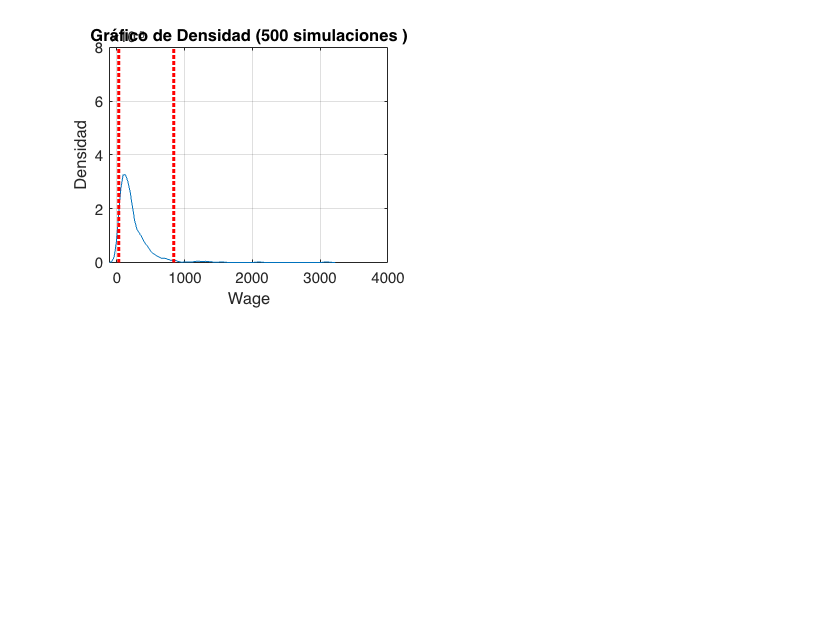



 %% Realizamos las graficas  de densidad con el intervalo de confianza
subplot(2,2,1)
ksdensity(Wage1_Normal)
grid on
line([pw2normal(1,1) pw2normal(1,1)], ylim*2,'Color','r','LineStyle',':','LineWidth',2)
line([pw2normal(1,2) pw2normal(1,2)], ylim,'Color','r','LineStyle',':','LineWidth',2)
xlabel('Wage') 
ylabel('Densidad')
title('Gráfico de Densidad (500 simulaciones )')

% Definamos las semilla 
rng(1234)

% c. Generamos 10000 errores aletarios para el modelo
S=std(Modelo2.Residuals.Raw,'omitnan');
mu=mean(Modelo2.Residuals.Raw);
RNormal=normrnd(0,S,[1,10000]);

% Intervalo de confianza del 95%
% Suponiendo un error con distribucion normal sin simulaciones 

betahat=Modelo2.Coefficients.Estimate;
LWh1_Normal=betahat(1,1)+betahat(2,1)+betahat(3,1)+betahat(4,1)+betahat(5,1)+betahat(6,1)+betahat(7,1)+betahat(8,1);


% Estimamos el exponencial del modelo2
% densidad y limites de prediccion:
Wage1_Normal=exp(RNormal'+LWh1_Normal)

Wage1_Normal = 	1.0e+03 *

    0.0719
    0.2451
    0.1313
    0.4185
    0.4651
    0.1123
    0.1088
    0.4695
    0.3122
    0.2584


pw3normal=prctile(Wage1_Normal, [2.5 97.5])

pw3normal =    31.9439  783.9730


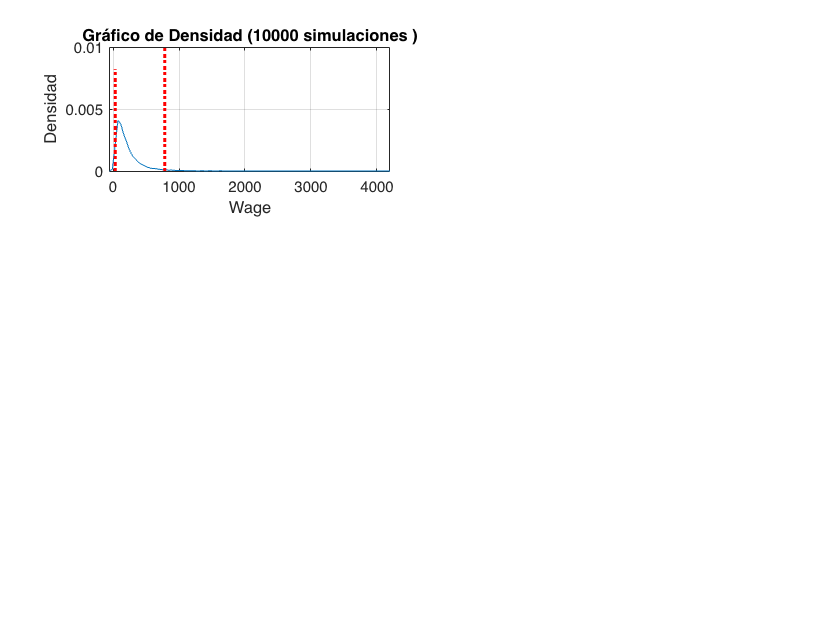




%% Realizamos las graficas  de densidad con el intervalo de confianza
subplot(3,2,1)
ksdensity(Wage1_Normal)
grid on
line([pw3normal(1,1) pw3normal(1,1)], ylim*2,'Color','r','LineStyle',':','LineWidth',2)
line([pw3normal(1,2) pw3normal(1,2)], ylim,'Color','r','LineStyle',':','LineWidth',2)
xlabel('Wage') 
ylabel('Densidad')
title('Gráfico de Densidad (10000 simulaciones )')

## Punto 4



%4.	Ahora supongan que no conoce la distribución de εi, excepto que
% estas tienen media cero. construyan 
% un intervalo de confianza de 95% para su pronóstico asumiendo R=10.000.
%a. generamos 10.000 numeros aleatorios que se obtienen directamente de los errores estimados:

RNoP = datasample(Modelo2.Residuals.Raw,10000);



betahat=Modelo2.Coefficients.Estimate;
Wage1_NoP=exp(RNoP'+LWh1_Normal);

% c. calculamos los intervalos de predicción a 95% de confianza:


pw1NoP = prctile(Wage1_NoP, [2.5 97.5])

pw1NoP =    20.5052  650.7080


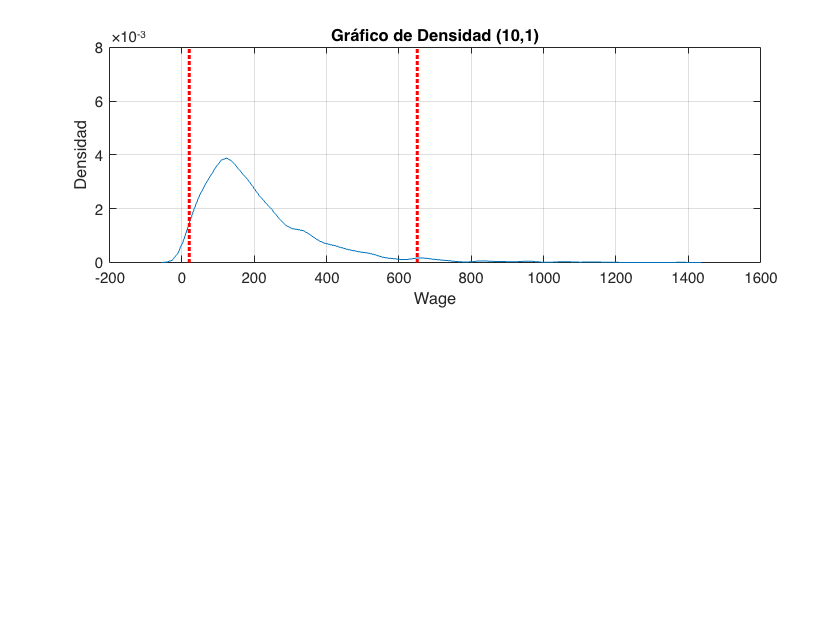

% e. se hace la funcion de densidad y se gráfica

%%  Punto 5 Realizamos Densidad y graficamos 
figure

subplot(2,1,1)
ksdensity(Wage1_NoP)
grid on
line([pw1NoP(1,1) pw1NoP(1,1)], ylim*2,'Color','r','LineStyle',':','LineWidth',2)
line([pw1NoP(1,2) pw1NoP(1,2)], ylim,'Color','r','LineStyle',':','LineWidth',2)

xlabel('Wage') 
ylabel('Densidad')
title('Gráfico de Densidad (10,1)')

## punto 6

betasigma=Modelo2.CoefficientCovariance;

RBetas = mvnrnd(betahat,betasigma,10000);

% c. se generan 10.000 simulaciones de los pronosticos con los betas y los errores
% simulados.

Wage1_Betas=[];
for i=1:10000
    Wage1_Betas(i)=exp(RBetas(i,1)+RBetas(i,2)+RBetas(i,3)+RBetas(i,4)+RBetas(i,5)+RBetas(i,6)+RBetas(i,7)+RBetas(i,8)+RNoP(i,:));
end
pw1betas = prctile(Wage1_Betas, [2.5 97.5])

pw1betas =    20.6491  647.4872


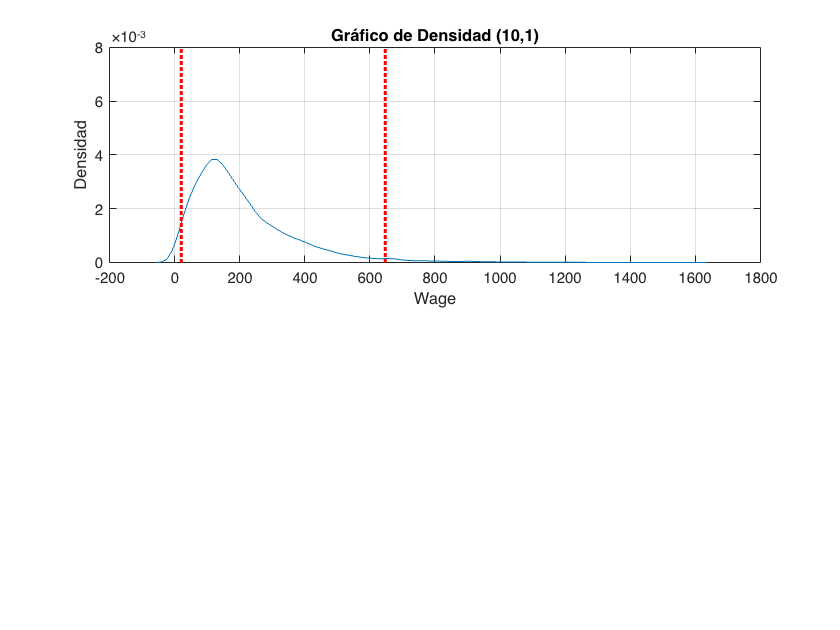

%% Punto 7  Realizamos las Graficas de densidad y intervalos de confianza
subplot(2,1,1)
ksdensity(Wage1_Betas)
grid on
line([pw1betas(1,1) pw1betas(1,1)], ylim*2,'Color','r','LineStyle',':','LineWidth',2)
line([pw1betas(1,2) pw1betas(1,2)], ylim,'Color','r','LineStyle',':','LineWidth',2)
xlabel('Wage') 
ylabel('Densidad')
title('Gráfico de Densidad (10,1)')

## Punto 8

betahat=Modelo2.Coefficients.Estimate;
Wage1_NoP=exp(LWh1_Normal);
pw1NoP = prctile(Wage1_NoP, [2.5 97.5])

pw1NoP =   156.9815  156.9815
